# ** Euler Method**

## 
$$y_{n+1} =y_n +h\cdot f\left(x_n ,y_n \right)$$


clear all;
format long;

% params
f = @(x, y) cos(x) + sin(x);
y(1) = 1;
xn = 0.8;
x0 = 0;
h = 0.2;

% function
x = x0:h:xn;

for n = 1:length(x)-1
    y(n+1) = y(n) + h * f(x(n), y(n));
    fprintf('Approximate value of y(%f) = %f\n', x(n+1), y(n+1))
end

x
y
plot(x, y, '*-', 'LineWidth', 1.3);
hold on;
soln = dsolve('Dy = cos(x) + sin(x)', 'y(0)=1', 'x')
xt = x0:0.01:xn;
yt = subs(soln, xt);
plot(xt, yt, 'LineWidth', 1.3);
hold off;
legend('Approx Solution', 'Actual Solution')

clear all;
format long;

% params
f = @(x, y) x.^2 + y.^2;
y(1) = 1;
xn = 1;
x0 = 0;
h = 0.2;

% function
x = x0:h:xn;

for n = 1:length(x)-1
    y(n+1) = y(n) + h * f(x(n), y(n));
    fprintf('Approximate value of y(%f) = %f\n', x(n+1), y(n+1))
end

Approximate value of y(0.200000) = 1.200000
Approximate value of y(0.400000) = 1.496000
Approximate value of y(0.600000) = 1.975603
Approximate value of y(0.800000) = 2.828205
Approximate value of y(1.000000) = 4.555953



x

x =                    0   0.200000000000000   0.400000000000000   0.600000000000000   0.800000000000000   1.000000000000000


y

y =    1.000000000000000   1.200000000000000   1.496000000000000   1.975603200000000   2.828204800770048   4.555953279789797


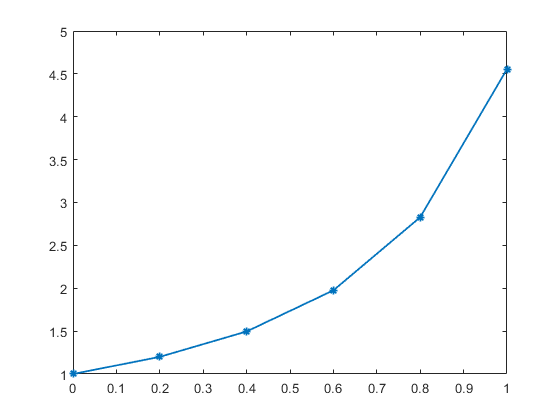

plot(x, y, '*-', 'LineWidth', 1.3);

hold on;
soln = dsolve('Dy = x^2 + y^2', 'y(0)=1', 'x')
xt = x0:0.01:xn;
yt = subs(soln, xt);
plot(xt, yt, 'LineWidth', 1.3);
hold off;
legend('Approx Solution', 'Actual Solution')